# Laplace Transform Applications

## Problem 1

Create a Laplace transform expression $F(s)$ for the following graphical functions in the time-domain $f(t)$. See the [**Laplace Transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) table for common transforms that can be used to build the overall function from individual functions such as a step or ramp.

### Problem 1a

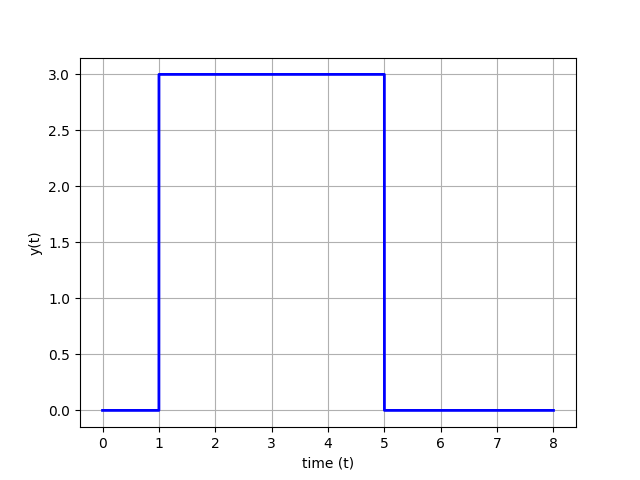

### Problem 1b

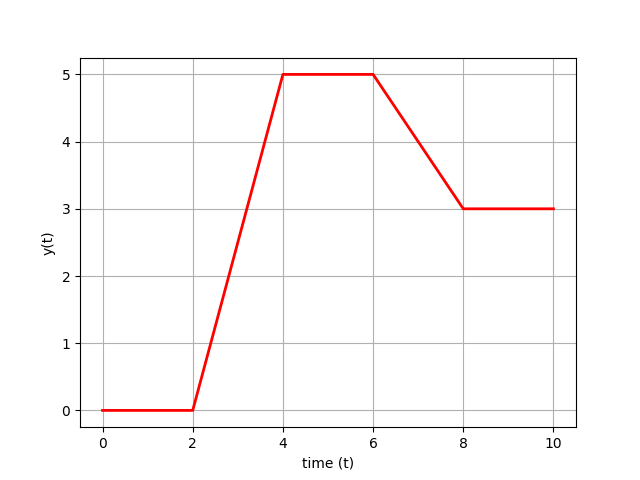

### Problem 1c

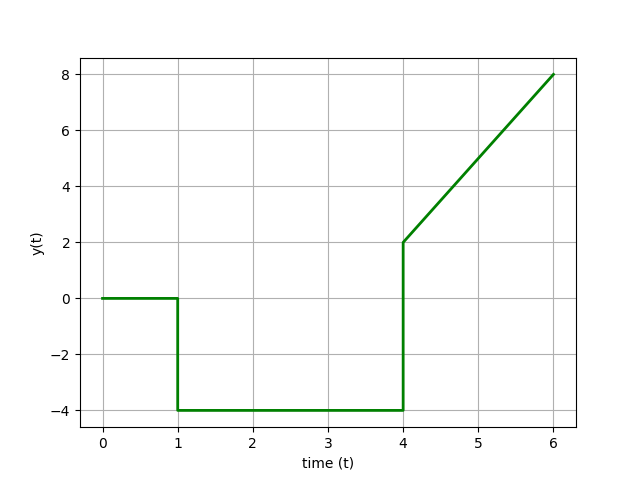

## Problem 2

Create a Laplace transform expression $F(s)$ for the following mathematical functions in the time-domain $f(t)$. See the [**Laplace Transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) table for common transforms.

### **Problem 2a**


$$f(t)=8t$$


### **Problem 2b**


$$f(t) = 2 \, S\left(t-3\right)$$


$S(t)$ is a step function with $S(t\le0)=0$ and $S(t\gt0)=0$.

### **Problem 2c**


$$f(t)=5 \frac{dy(t)}{dt}$$


### **Problem 2d**


$$f(t)=5\int y(t)dt$$


## Problem 3

Transform the elements of the following differential equations in time domain into an equivalent differential equation in the Laplace domain. Because the Laplace transform is a linear operator, each element can be transformed separately. Rearrange the equation in the Laplace domain and perform an inverse Laplace transform to solve for an analytic expression of $y(t)$.

### Problem 3a


$$\frac{dy(t)}{dt}=-ky(t)$$


where $k$ is a constant and with the initial condition $y(0)=5$.

### Problem 3b


$$\frac{d^2y(t)}{dt^2}+2\frac{dy(t)}{dt}+y(t)=5$$


with initial conditions $y(0)=0$, $\frac{dy(0)}{dt}=0$, and $\frac{d^2y(0)}{dt^2}=0$.

### Problem 3c

A [**first-order linear differential equation**](https://apmonitor.com/pdc/index.php/Main/FirstOrderSystems) is shown as a function of time with constants $\tau$ and $K$ and variables $y(t)$ and $u(t)$. Assume zero initial conditions for the variables.


$$\tau \frac{dy(t)}{dt} = -y(t) + K \, u(t)$$


Derive an analytic solution for $y(t)$ with input doublet $u(t)$ from Problem 1a.

Create a plot of $y(t)$ and $u(t)$ with constant values $K=1$ and $\tau=2$.

K = 1
tau = 2

t = linspace(0,8,81).'

step1 = zeros(81,1)
step1(11:end) = 1

step2 = zeros(81,1)
step2(51:end) = 1

y = 0

plot(t,y)

## Solution

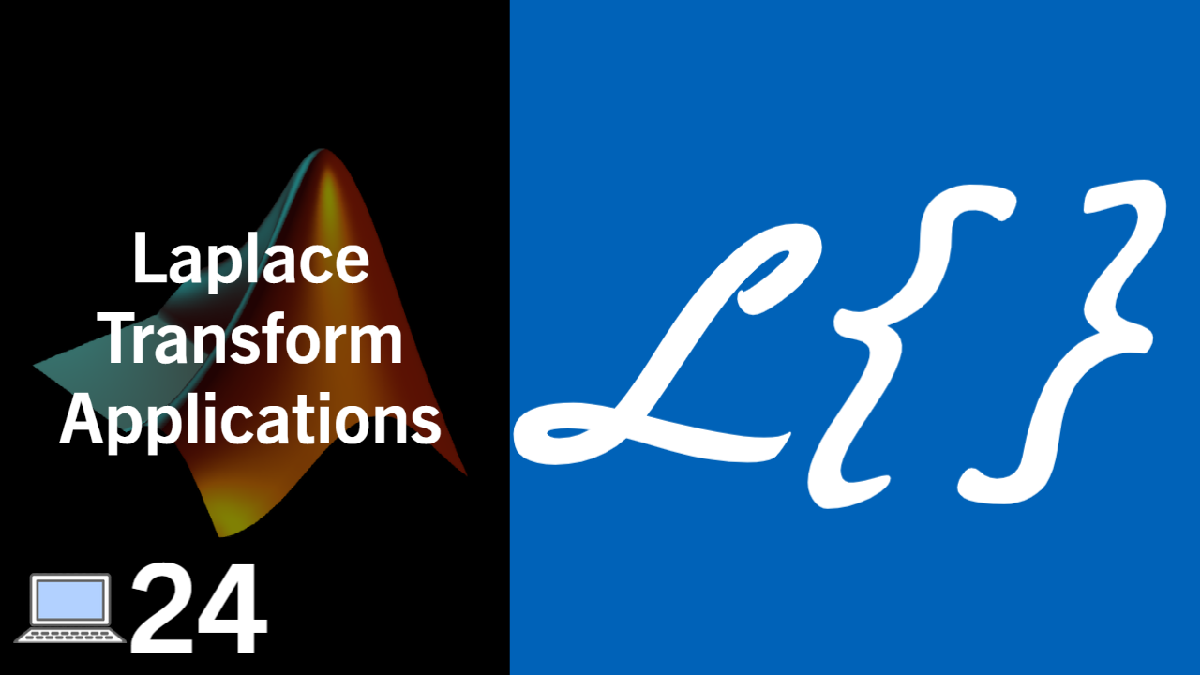

### [View Solution](https://youtu.be/xuST-bLKQwQ)

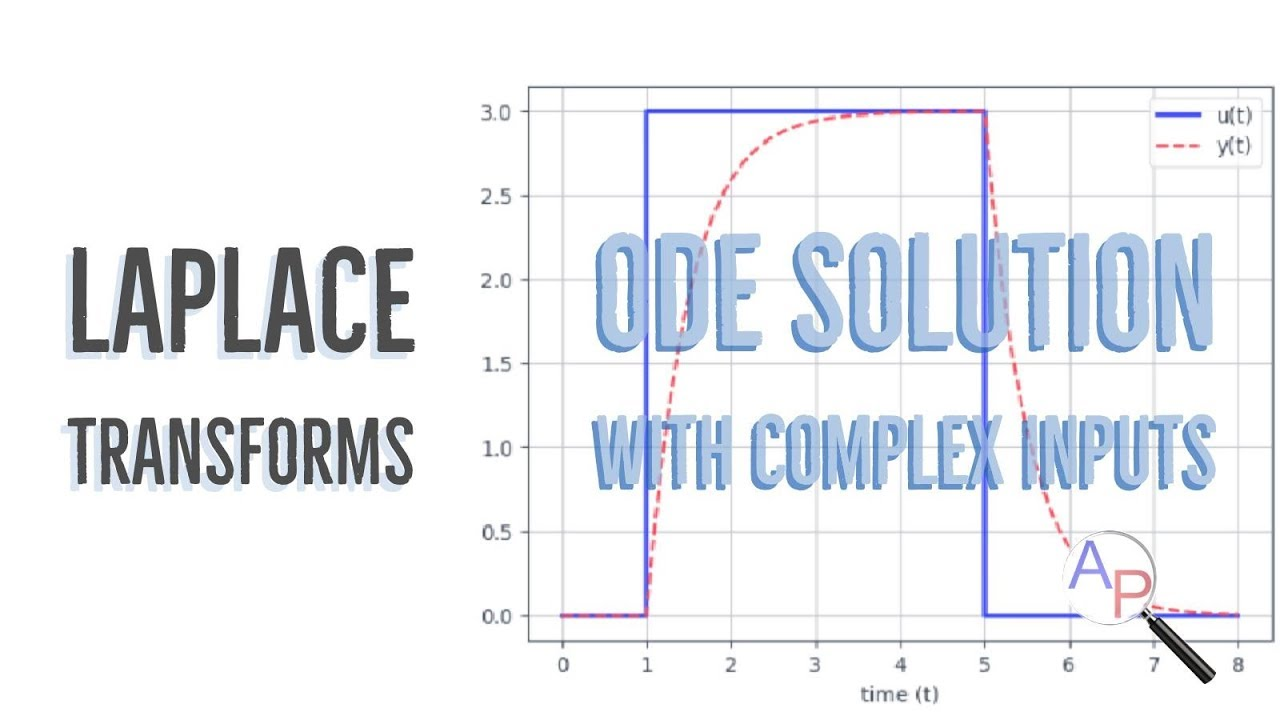

### [View Solution Video](https://www.youtube.com/watch?v=-BlZrq9WtZs)

**Correction:** The video solution is incorrect for problem 2b and 3b. It is $\frac{2}{s} e^{-3s}$ for 2b and it is $\frac{5}{s}$ (not just 5) on the right side of the equation when performing the Laplace transform of a constant.

**Problem 3 Solution Help**

The first step is to apply the [**Laplace transform**](https://apmonitor.com/pdc/index.php/Main/LaplaceTransforms) to each of the terms in the differential equation. Because the Laplace transform is a linear operator, each term can be transformed separately. With a zero initial condition the value of $y$ is zero at the initial time or $y(0)=0$.


$$\mathcal{L}\left(\tau_p \frac{dy(t)}{dt}\right) = \tau_p \left(s \, Y(s) - y(0)\right) = \tau_p s \, Y(s)$$



$$\mathcal{L}\left(-y(t)\right) = -Y(s)$$



$$\mathcal{L}\left(K \, u(t)\right) = K \, U(s)$$


Putting these terms together gives the first-order differential equation in the Laplace domain.


$$\tau \, s \, Y(s) = -Y(s) + K \, U(s)$$


The differential equation as a function of time (*t*) is now an algebraic equation in the Laplace domain (*s*) that can be further manipulated into [**Transfer Function**](https://apmonitor.com/pdc/index.php/Main/TransferFunctions) form. Transfer functions are covered in the next lecture and help built more complex descriptions of dynamic systems.